clear;


f0 = 60e9;  
% f0 = 60.25e9;  
c = physconst('lightspeed'); 
lambda = c / f0; 
D = lambda / 2; 
num_rx = 4; 
% num_tx = 3; 
num_tx = 2;
chirp_num = 128;

idel_time = 30e-6; 
ramp_time = 80e-6; 
TC = (idel_time + ramp_time) * num_tx; 
TF = TC * chirp_num;
frame_length = 60; 
overlap = 0.25;
% slope = 46.395e12;
slope = 49.97e12;
adc_sample = 256; 
fs_sample=6500e3;
% fs_sample=10000e3;



% [ADC_DATA] = readDCA1000('7.26/Z_41_Raw_0.bin');
[ADC_DATA] = readDCA1000('bu2_Raw_0.bin');
% [ADC_DATA] = readDCA1000('Z1_bu2_Raw_0.bin');

load('recdata.mat');
fs = rectdata.fs;
propspeed = rectdata.propspeed;
fc = rectdata.fc;
rxdata = rectdata.rxdata;
mfcoeffs = rectdata.mfcoeffs;
%noisepower = rectdata.noisepower;
% antennaarray = rectdata.antennaarray;
antennaarray=phased.ULA( ...
    'NumElements',4, ...
    'ElementSpacing', 0.02,"ArrayAxis", 'y',...
    'Taper', 1);


% rngangresp = phased.RangeAngleResponse(...
%     'SensorArray',antennaarray,'phased.RangeAngleResponse',62e9,...
%     'RangeMethod','FFT',... 
%     'SampleRate',fs_sample,'PropagationSpeed',propspeed);

rngangresp = phased.RangeAngleResponse(...
    'SensorArray',antennaarray,'OperatingFrequency',fc,...
    'RangeMethod','FFT',... 
    'SampleRate',fs_sample,'PropagationSpeed',propspeed);

H = phased.RangeDopplerResponse(...
    'RangeMethod','FFT',...
    'SampleRate',fs_sample,...
    'ReferenceRangeCentered',false,...
    'SweepSlope',slope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',adc_sample,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',chirp_num);



% data_each_frame = adc_sample*chirp_num;
%     for i = 1:frame_length/2
%         data_frame = ADC_DATA(:, (i-1)*data_each_frame+1:i*data_each_frame);
%         data_chirp = [];
% %         for cj = 1:num_tx*chirp_num
%         for cj = 1:chirp_num
%             temp_A_data = data_frame(:, (cj-1)*adc_sample+1:cj*adc_sample);
%             data_chirp(:,:,cj) = temp_A_data;
%         end
%         
%         
%         data_chirp = permute(data_chirp, [2,1,3]);
%         
%         ra = squeeze(sum(data_chirp,3)/size(data_chirp,3));
%         
% %         X_raw = detrend(ra,0); %去除直流分量
%         X_raw=ra;
%         
%         [resp,rng_grid,ang_grid] = rngangresp(X_raw);
%        
%         figure(i)
%         %     h = heatmap(X_slow(10:59,:));
%         h = heatmap(abs(resp));
%         colormap(gca, 'parula');
%         grid off;  
%         break
%      end
        
        
    adc_tx1 = ADC_DATA(:,1:2:end);
    temp_data = reshape(adc_tx1,4,adc_sample,[]);
%     adc_tx1 = temp_data(:,:,1:2:end);
%         temp_data=squeeze(sum(temp_data,1)/size(temp_data,1));
%         select_data=squeeze(sum(data_chirp,2)/size(data_chirp,2));
    overlap=0.25; 
    temp_index = [5 : 100];
    for frame_idx = 1 : (frame_length -1) / overlap +1
        select_data = temp_data(:,:,[1:chirp_num]+chirp_num*overlap*(frame_idx-1));
        select_data_rd=squeeze(sum(select_data,1)/size(select_data,1));
        select_data_rd1 = select_data_rd - mean(select_data_rd,1); % 滤除静态杂波
        select_data_rd1 = select_data_rd1 .* hanning(adc_sample); % 加窗
        range_profile = fft(select_data_rd1,adc_sample,1); % 距离fft 
        range_profile = range_profile - repmat(mean(range_profile'),size(range_profile,2),1)'; % 滤除速度为0目标
        
        
%         R_raw = detrend(select_data_rd,0); %去除直流分量
        [R_resp,rnggrid,dopgrid] = step(H,select_data_rd1);
        R_abs = abs(R_resp);
        R_abs(:,65)=0;%令0频doppler等于0   
        R_max =  max(R_abs,[],2); %取出每个距离doppler的最大值
        R_slow(:,frame_idx) = R_max;

%         range_profile = detrend(range_profile,0); %去除直流分量
        
        doppler_profile = fftshift(fft(range_profile,chirp_num,2),2); % 多普勒fft

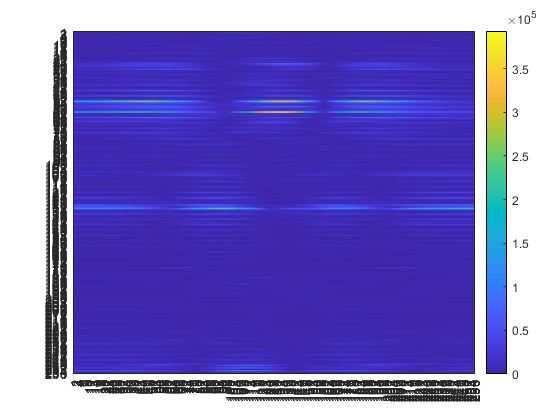

        
        
        dsum = abs(doppler_profile).^2;
        rsum = zeros(size(dsum,1),1);
%         rsum(temp_index) = sum(dsum(temp_index,:),2);
        rsum = max(dsum,[],2);
        doppler_profile = (abs(doppler_profile(temp_index,:)).^2 );
        ud_plot(:,frame_idx) = sum(doppler_profile).';
        rt_plot(:,frame_idx) = rsum; 
        
        
     
        select_data_ang = permute(select_data, [2,1,3]);
        select_data_ang=squeeze(sum(select_data_ang,3)/size(select_data_ang,3));
%         X_raw = detrend(select_data_ang,0); %去除
        select_data_ang = select_data_ang - mean(select_data_ang,1); 
        [resp,rng_grid,ang_grid] = rngangresp(select_data_ang);

        X_abs = abs(resp);
%         X_abs = resp;
        X_abs(129,:)=0;%令0频doppler等于0   
        X_max =  max(X_abs([10:240],[30:230]),[],1); %取出每个距离doppler的最大值
        X_max=X_max';
        X_slow(:,frame_idx) = X_max;
        
    end
    ud_plot(:,end - 1 / overlap + 2 : end) = repmat(ud_plot(:,(frame_length - 1) / overlap + 1),1,1 / overlap - 1);
    rt_plot(:,end - 1 / overlap + 2 : end) = repmat(rt_plot(:,(frame_length - 1) / overlap + 1),1,1 / overlap - 1);

    
    
    figure(4)
%     h = heatmap(X_slow(10:59,:));
 h = heatmap(abs(resp));
    colormap(gca, 'parula');
    grid off;  

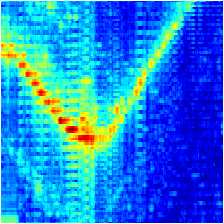

    
%         rt_data = db_rt_plot(:,init_idx+interval_idx*(fra_idx-1):end_idx+interval_idx*(fra_idx-1));
%         ud_data = db_ud_plot(:,init_idx+interval_idx*(fra_idx-1):end_idx+interval_idx*(fra_idx-1));
        
%         db_rt_plot = db(rt_plot(5:100,:)+eps)/2;
        db_rt_plot = db(rt_plot(5:100,:)+eps)/2;
        db_ud_plot = db(ud_plot+eps)/2;
%         db_X_slow=db(X_slow+eps)/2;
       


        
%      break   

        figure(31);
        imagesc(db_rt_plot);
        colormap('jet');

%             caxis([80 110]);
        axis xy;
        set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
        set(gcf,'position',[1500,400, 224, 224]);
        set(gca,'looseInset',[0 0 0 0]);

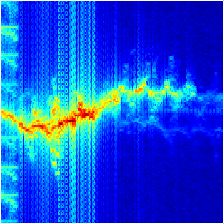


        
%         figure(30)
%         h = heatmap(db_rt_plot);
%         colormap(gca, 'parula');
% %         colormap('jet');
%         grid off;
        
        
        
        
        db_ud_plot(65, :) = [];
        figure(32);
        imagesc(db_ud_plot);
        colormap('jet');
%             caxis([80 110]);
        axis xy;
        set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
        set(gcf,'position',[1500,400, 224, 224]);
        set(gca,'looseInset',[0 0 0 0]);

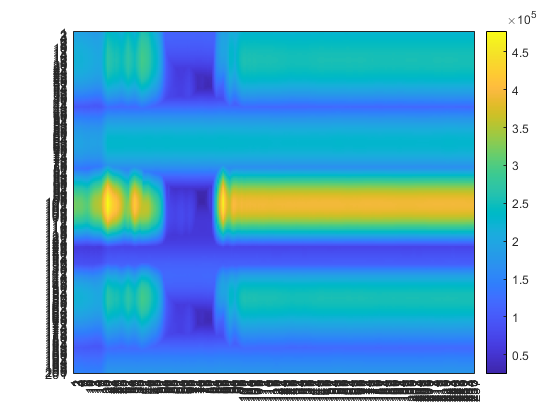

        
        
%         db_ud_plot(65, :) = [];    
%         figure(60)
% %         h = heatmap(X_slow(10:59,:));
%         h = heatmap(db_ud_plot);
% %         colormap(gca, 'parula');
%         colormap('jet');
%         grid off;
        

        
%         plotResponse(rngangresp,X_raw,'Unit','db');
        
        
        
        figure(90)
%         h = heatmap(X_slow(10:59,:));
        h = heatmap(X_slow);
        colormap(gca, 'parula');
%         colormap('jet');
        grid off;

        
        
%         figure(91)
%         h = heatmap(R_slow(5:127,:));
%         colormap(gca, 'parula');
% %         colormap('jet');
%         grid off;
        
%         figure(90+i);
%         imagesc(X_slow);
%         colormap('jet');
% %             caxis([80 110]);
%         axis xy;
%         set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
%         set(gcf,'position',[1500,400, 224, 224]);
%         set(gca,'looseInset',[0 0 0 0]);




% %% TI官方处理代码

function [retVal] = readDCA1000(fileName)
%% global variables
% change based on sensor config
numADCSamples = 128; % number of ADC samples per chirp
numADCBits = 16; % number of ADC bits per sample
numRX = 4; % number of receivers
numLanes = 2; % do not change. number of lanes is always 2
isReal = 0; % set to 1 if real only data, 0 if complex data0
%% read file
% read .bin file
fid = fopen(fileName,'r');
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
fileSize = size(adcData, 1);
% real data reshape, filesize = numADCSamples*numChirps
if isReal
    numChirps = fileSize/numADCSamples/numRX;
    %create column for each chirp
    LVDS = reshape(adcData, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
else
    % for complex data
    % filesize = 2 * numADCSamples*numChirps
    numChirps = fileSize/2/numADCSamples/numRX;
    LVDS = zeros(1, fileSize/2);
    %combine real and imaginary part into complex data
    %read in file: 2I is followed by 2Q
    counter = 1;
    for i=1:4:fileSize-1
        LVDS(1,counter) = adcData(i) + sqrt(-1)*adcData(i+2); 
        LVDS(1,counter+1) = adcData(i+1)+sqrt(-1)*adcData(i+3); 
        counter = counter + 2;
    end
    % create column for each chirp
    LVDS = reshape(LVDS, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
end
%organize data per RX
adcData = zeros(numRX,numChirps*numADCSamples);
for row = 1:numRX
    for i = 1: numChirps
        adcData(row, (i-1)*numADCSamples+1:i*numADCSamples) = LVDS(i, (row-1)*numADCSamples+1:row*numADCSamples);
    end
end
% return receiver data
retVal = adcData;
end
